# **Arrays and Matrices**

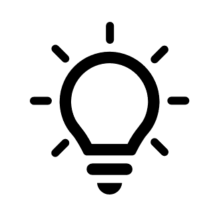 Where do I find MATLAB? [Here](https://www.mathworks.com/academia/tah-portal/wits-university-40783970.html)!

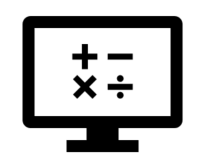 Do I have to have MATLAB installed on my computer right now? No, you can use  [MALAB Online](https://matlab.mathworks.com/)!

## Recap of Week 1: Introduction and Data Types

Last week, we learnt about:

- What programming is

- What MATLAB is

- Data types

- Variables and Commands

- Mathematical Functions

- MATLAB Live Editor

This week we have split the content into two parts. We begin with Part 1: Arrays and Matrices, which covers the following: 

- What arrays and matrices are

- Creating arrays

- Indexing into arrays 

- Concatenation of arrays

- Operating with function on arrays

## Arrays and Matrices 

### Introduction to arrays and matrices

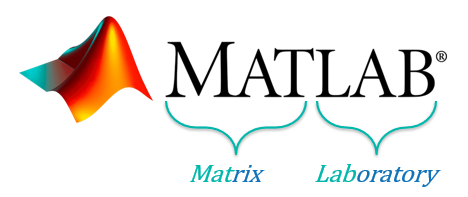

The name MATLAB is an abbreviation of "MATrix LABoratory". MATLAB was designed to work with matrices as the fundamental unit of data. A matrix is regular two-dimensional grid, or table, of numbers, with rows and/or columns.

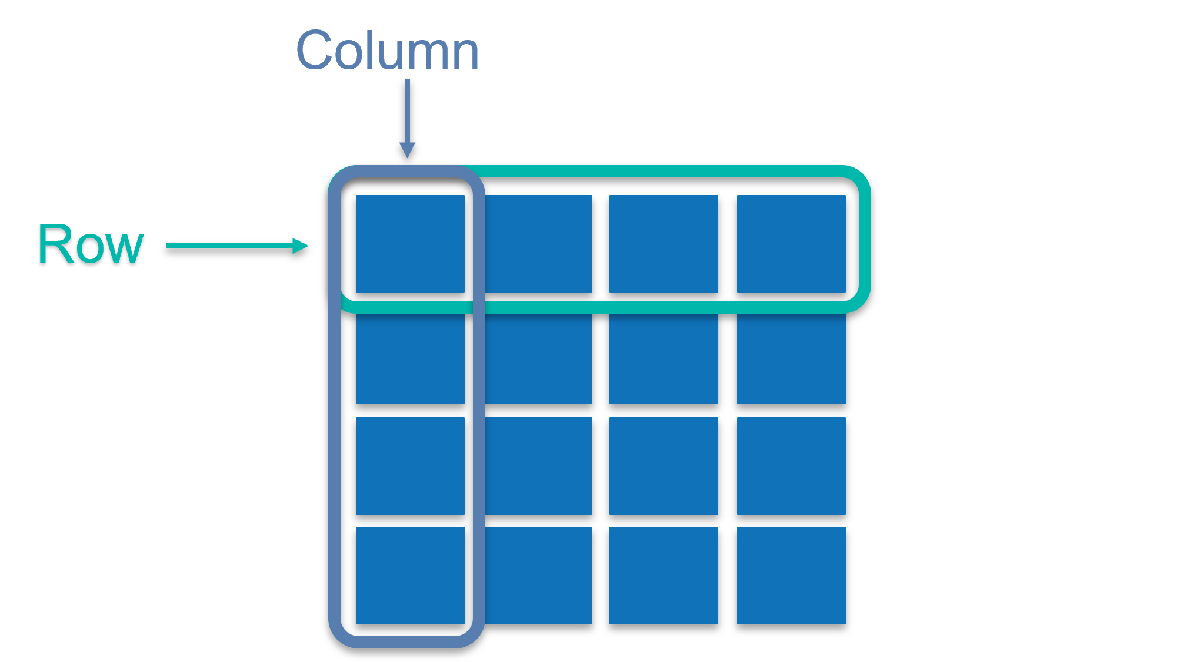

They can come in many shapes and sizes,  

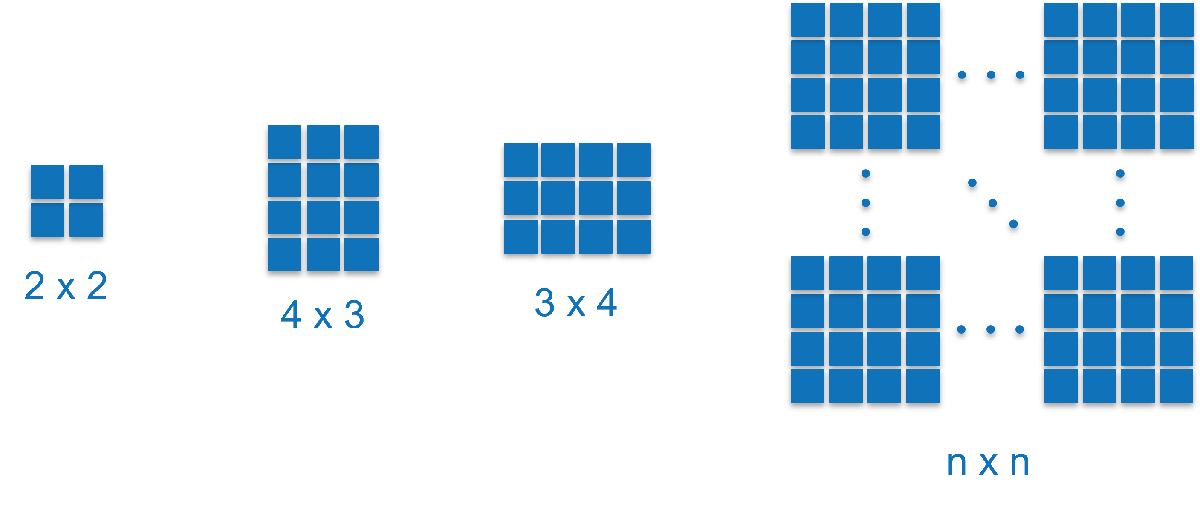

and we have a special case when there is only a single row and/or column. Let us consider what MATLAB understands [arrays and matrices](https://www.mathworks.com/help/matlab/learn_matlab/matrices-and-arrays.html) to be. Refer to the image below, beginning at the smallest, inner most oval and working our way to the largest, outer most oval. When there is only one row and one column, we have a scalar value. A scalar value would be any numerical value that includes the digits 0 to 9, in a positive or negative form, for example `5` or `-5`. 

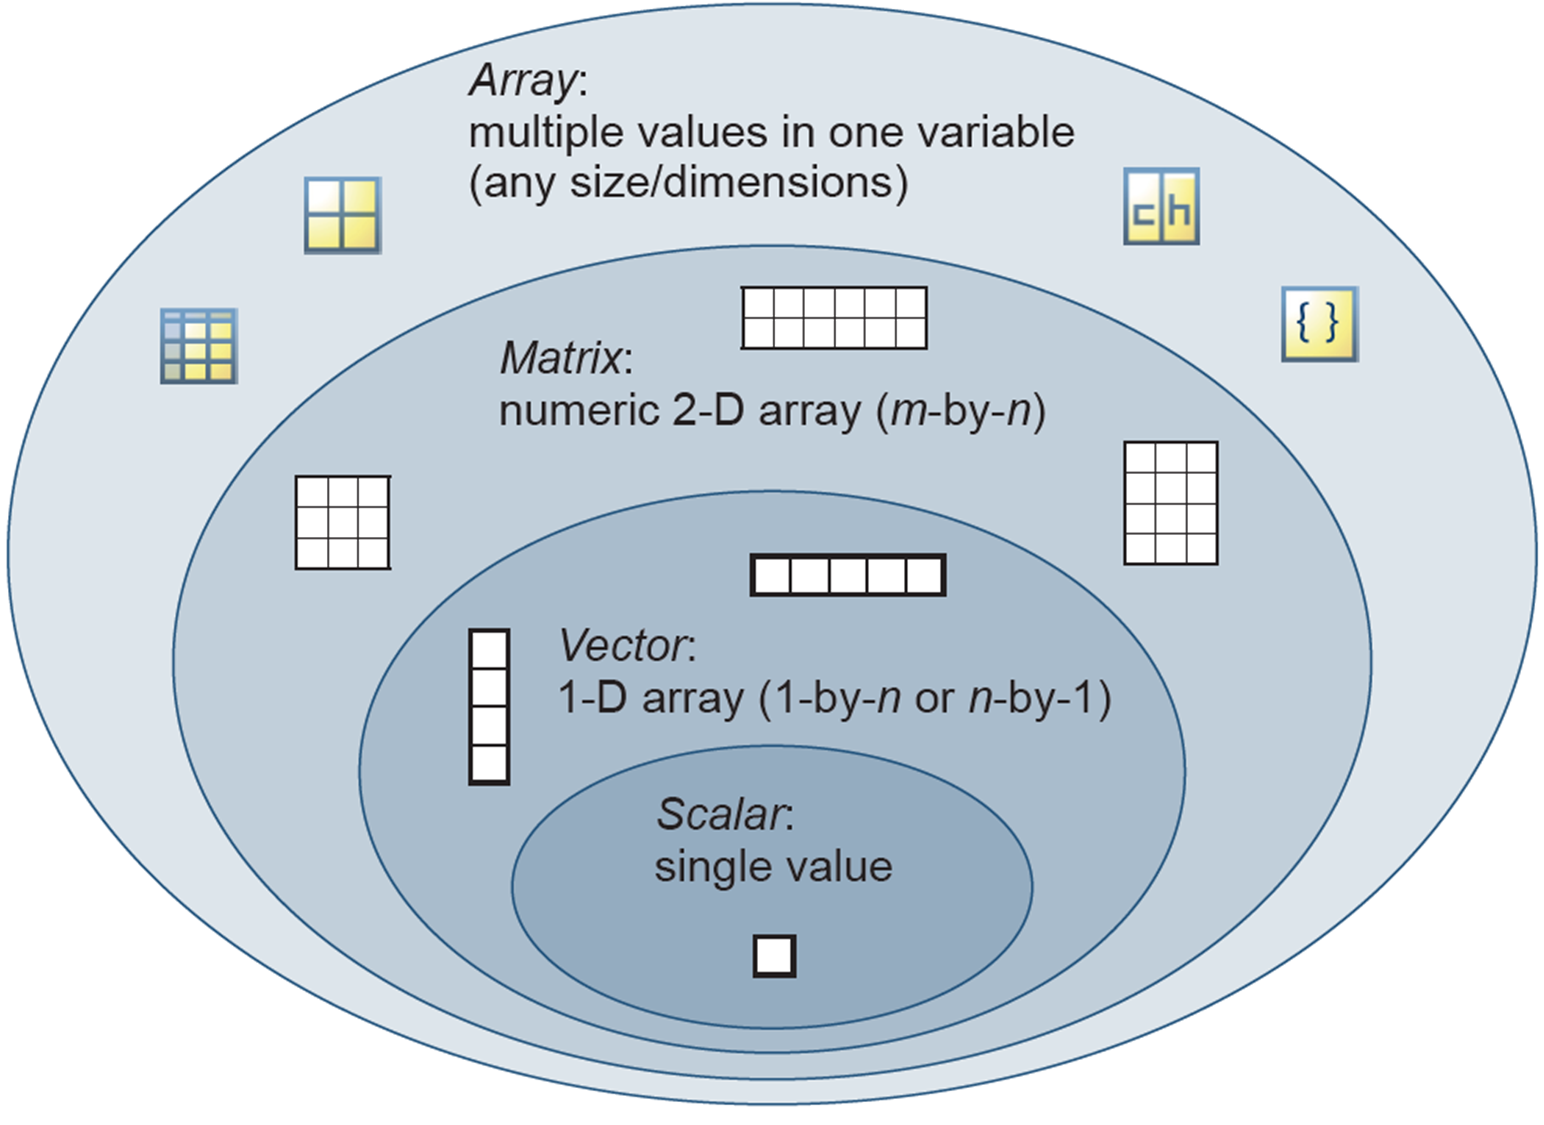

When there is a single row or column, we have a vector. A vector is a collection of scalar values/elements arranged in row or column form and is also known as a 1-D numeric array. Combining row or column vectors results in a matrix, which is also referred to as a 2-D numeric array. When you wish to include data that is not in numeric form, we refer to the variable simply as an array. An array can have multiple data types and values in one variable and can be of any size/dimension. Examples of arrays include: 

- Numeric arrays

- Character arrays

- Cell arrays

- Tables

You interact with applications of matrices and arrays in your everyday life, with images being likely the most common one. An image is stored in electronic devices as arrays or matrices, where each pixel in the image is represented by a single element in an 2-dimensional array or matrix. For grayscale images, only one matrix is stored with element values between 0 (white) and 1 (black). Colour images are a collection of three array/matrix layers based on RGB code, i.e. a matrix for Red, Green, and Blue coded numerical values. 

Now you try! Run the following code will import a stock image from MATLAB, convert it to grayscale, and display it. 

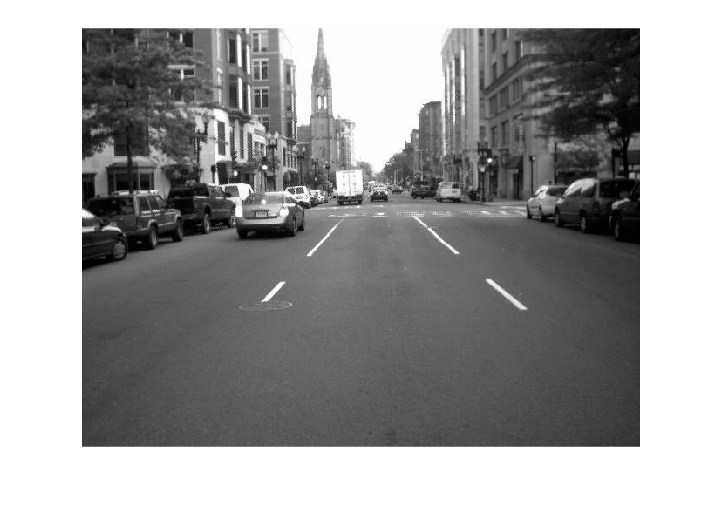

A = imread('street1.jpg');
B = rgb2gray(A);
imshow(B)

Take a look in the workspace at the variables created in the code above. You'll notice that A is an array with three matrices (one for each RGB layer) with 480 rows and 640 columns each, and B is a matrix with 480 rows and 640 columns. The number of pixels in an image is determined by taking the number of rows and multiplying it by the number of columns, i.e. for this image there are `307 200` pixels. 

### Array creation

**Creating vectors by specifying each element individually**

We use square brackets, $\left\lbrack \right\rbrack$, in MATLAB to denote numeric arrays. There are a few ways of creating an array in MATLAB. As MATLAB's convention defines observations as rows and columns as variables of the observations, let us begin by creating some row vectors. To separate values in a row vector you can either use a space or a comma:

a_1 = [1 2 3 4]

a_1 =      1     2     3     4


a_2 = [1, 2, 3, 4]

a_2 =      1     2     3     4


Note: MATLAB interprets a comma as a separator and not a decimal point. 

To create a column vector, simply use a semi-colon to separate the values:

a_3 = [1; 2; 3; 4]

a_3 =      1
     2
     3
     4


You can interchange between row and column vectors by transposing between one and the other. This is done by including an inverted comma after the closing square bracket, for example

a_4 = [1; 2; 3; 4]'

a_4 =      1     2     3     4


Now you try! Create a row vector called `x_1` with the values `2`, `4`, `6`, and `8`.

x_1 = [2, 4, 6, 8]

x_1 =      2     4     6     8


**Creating vectors of equally spaced element values**

Typing out each element of a vector can be tedious and time consuming. In the case where you require a vector to be created with equally spaced element values, there are two approaches available. 

Method 1: Using the notation `var = start : step size : end`

a_5 = 1:2:10

a_5 =      1     3     5     7     9


a_6 = 10:-2:1

a_6 =     10     8     6     4     2


We use the colon operator to create regularly spaced vectors, index into arrays, and define the bounds of a `for` loop. For now, we are considering its application in vector creation, but we will get to its other applications later on. 

You will notice that the specified "end" value is not necessarily the last element's value when using this approach, as with the output for variable `a_6.` This is a distinct difference between this approach and the following one. Another important property of this approach is that if you do not specify the "step size" in this notation, MATLAB will assume you are requesting for a step size of 1.

a_7 = 1:4

a_7 =      1     2     3     4


Now you try! Create a row vector `x_3` that spans from $-2\pi$ to $2\pi$ equally spaced of `0.2`

x_3 = -2*pi:0.2:2*pi

x_3 =    -6.2832   -6.0832   -5.8832   -5.6832   -5.4832   -5.2832   -5.0832   -4.8832   -4.6832   -4.4832   -4.2832   -4.0832   -3.8832   -3.6832   -3.4832   -3.2832   -3.0832   -2.8832   -2.6832   -2.4832   -2.2832   -2.0832   -1.8832   -1.6832   -1.4832   -1.2832   -1.0832   -0.8832   -0.6832   -0.4832   -0.2832   -0.0832    0.1168    0.3168    0.5168    0.7168    0.9168    1.1168    1.3168    1.5168    1.7168    1.9168    2.1168    2.3168    2.5168    2.7168    2.9168    3.1168    3.3168    3.5168


Method 2: Using the built in function `var = linspace(start, end, number of elements)`

a_8 = linspace(1,10,5)

a_8 =     1.0000    3.2500    5.5000    7.7500   10.0000


This approach gives the user direct control of the number of points/elements and ensures that the last element of the vector is the value specified by the user. MATLAB automatically calculates what step size is required given the user's input to the function. It is important to note that if the number of points/elements is not specified by the user, MATLAB will assume a default value of 100 points is required.

Now you try! Create a row vector `x_4` that spans from `0` to `10` with `100` elements equally spaced.

x_4 = linspace(0,10)

x_4 =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495


**Creating vectors using other built-in functions**

There are a few built in functions you can leverage for creating vectors and matrices in MATLAB. This subsection will cover 3 examples of such functions, which will come in handy when trying to avoid computationally expensive iterative scripts/loops. Let us begin by creating a vector with all elements being the value `1,` and then a second vector where all elements have a value of `0`. Both of these functions expect two inputs, one for the number of rows, `r,` and the next for the number of columns, `c,` i.e. `var = ones(r, c) `or `var = zeros(r, c)`

b_1 = ones(1,5)

b_1 =      1     1     1     1     1


b_2 = zeros(1,5)

b_2 =      0     0     0     0     0


Next, let us create a vector or values drawn from a uniform distribution in the interval `(0, 1)`. The function `rand` is used to do this, following the same notation as the functions `ones` and `zeros`, `var = rand(r, c)`

b_3 = rand(1,5)

b_3 =     0.8147    0.9058    0.1270    0.9134    0.6324


Now you try! Create a row vector `x_5` that spans from `0` to `10` with `100` elements equally spaced.

x_5 = linspace(0,10)

x_5 =                    0   0.101010101010101   0.202020202020202   0.303030303030303   0.404040404040404   0.505050505050505   0.606060606060606   0.707070707070707   0.808080808080808   0.909090909090909   1.010101010101010   1.111111111111111   1.212121212121212   1.313131313131313   1.414141414141414   1.515151515151515   1.616161616161616   1.717171717171717   1.818181818181818   1.919191919191919   2.020202020202020   2.121212121212121   2.222222222222222   2.323232323232323   2.424242424242424   2.525252525252525   2.626262626262626   2.727272727272727   2.828282828282828   2.929292929292930   3.030303030303030   3.131313131313131   3.232323232323232   3.333333333333333   3.434343434343434   3.535353535353535   3.636363636363636   3.737373737373737   3.838383838383838   3.939393939393939   4.040404040404041   4.141414141414141   4.242424242424242   4.343434343434343   4.444444444444445   4.545454545454546   4.646464646464646   4.747474747474747   4.848484848484849   4.949494949

### **Array Indexing**

In this subsection, we will cover how to index into arrays to extract or reassign one or more elements. We begin by initialising an arbitrary variable matrix, `A:`

syms a11 a12 a13 a21 a22 a23 a31 a32 a33

Aside: You can look up the Symbolic Math Toolbox for more details on the above command however, this will be covered in a future section of this course.

A =[a11 a12 a13; a21 a22 a23; a31 a32 a33]

$$A = \left(\begin{array}{ccc} a_{11} & a_{12} & a_{13}\\ a_{21} & a_{22} & a_{23}\\ a_{31} & a_{32} & a_{33} \end{array}\right)$$

To index into a matrix, specify the row, `r`, and column, `c`, numbers of interest using the notation `MatrixName(r, c).` Let us access the element in the first row and the second column of the above matrix, `A` and assign it to a new workspace variable.

NewWorkspaceVariable_1 = A(1,2)

$$NewWorkspaceVariable\_1 = a_{12}$$

To extract an entire row or column, use a colon, `:`, instead of specifying the column or row number, for example let us extract the all the columns of row 1:

NewWorkspaceVariable_2 = A(1,:)

$$NewWorkspaceVariable\_2 = \left(\begin{array}{ccc} a_{11} & a_{12} & a_{13} \end{array}\right)$$

In a similar way, let us extract all rows of the second column:

NewWorkspaceVariable_3 = A(:,2)

$$NewWorkspaceVariable\_3 = \left(\begin{array}{c} a_{12}\\ a_{22}\\ a_{32} \end{array}\right)$$

When referencing rows or columns, MATLAB interprets a colon as **all** the rows or columns (as seen above). Sometimes only specific elements of the array are required, so being able to specify this in a single command is useful. MATLAB allows referencing elements in an array by specifying the indices/positions in an array, for example let us extract the elements from column 2 until the last column, of row 1 in matrix `A`: 

NewWorkspaceVariable_4 = A(1,2:end)

$$NewWorkspaceVariable\_4 = \left(\begin{array}{cc} a_{12} & a_{13} \end{array}\right)$$

You'll notice that instead of specifying the end index value, `3`, the syntax `end` was used. This is a convenient way to index the last element in an array without first determining its value, and this approach to coding assists with code readability. 

So far, we have covered how to reference from an array to create a new workspace variable. Now, we will consider how to replace/overwrite an element in an array. As we references a row and column above when extracting the element value, we now use assignment to that element value, i.e. the matrix reference will be on the left-hand side of the equals sign `MatrixName(r, c) = value`. Let us replace the element in column 3 of the first row with the value `10`: 

A(1,3)=10

$$A = \left(\begin{array}{ccc} a_{11} & a_{12} & 10\\ a_{21} & a_{22} & a_{23}\\ a_{31} & a_{32} & a_{33} \end{array}\right)$$

Note: The element $a_{13}$ has now been replaced by the value `10.` This operation cannot be undone, and the only way to have a value $a_{13}$ in column 3 of the first row, is to reassign that variable to the element position. 

The assignment operation to an array row or column can also be used to remove/delete the row or column respectively, by assigning the entire row or column to an empty array `[]`. As an example, let us remove the entire first row of the matrix `A:`

A(1,:) = []

$$A = \left(\begin{array}{ccc} a_{21} & a_{22} & a_{23}\\ a_{31} & a_{32} & a_{33} \end{array}\right)$$

Now you try! Create a 3-by-3 symbolic matrix `A` as demonstrated in the beginning of the Array indexing section. 

syms a11 a12 a13 a21 a22 a23 a31 a32 a33
A =[a11 a12 a13; a21 a22 a23; a31 a32 a33];

Extract the element from the third column and second row, and assign it to the variable `x_6`.

x_6 = A(2, 3)

$$x\_6 = a_{23}$$

Extract the entire third row, and assign it to the variable `x_7`.

x_7 = A(3, :)

$$x\_7 = \left(\begin{array}{ccc} a_{31} & a_{32} & a_{33} \end{array}\right)$$

Replace the element in third row and second column with the value `5`. 

A(3, 2) = 5

$$A = \left(\begin{array}{ccc} a_{11} & a_{12} & a_{13}\\ a_{21} & a_{22} & a_{23}\\ a_{31} & 5 & a_{33} \end{array}\right)$$

### **Array concatenation**

Array concatenation is the process of combining two or more arrays into a single array. There are two ways of concatenating arrays; horizontally and vertically, both of which use the notation you learnt in the Creating vectors by specifying each element individually subsection. 

To concatenate **horizontally**, simply use the square bracket (and comma) notation used when combining elements into a row vector, i.e. `NewMatrix = [Matrix_1 Matrix_2]` or `NewMatrix = [Matrix_1, Matrix_2]`. It is important that the **number of columns is the same** for all the arrays being concatenated. Let us try this operation by horizontally concatenating a **2-by-2 matrix **`A` with a **2-by-1** matrix (**column vector**) `x`:

syms a11 a12 a21 a22 x1 x2

Aside: You can look up the Symbolic Math Toolbox for more details on the above command however, this will be covered in a future section of this course.

A =[a11 a12; a21 a22]

$$A = \left(\begin{array}{cc} a_{11} & a_{12}\\ a_{21} & a_{22} \end{array}\right)$$

x = [x1; x2]

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

A = [A x]

$$A = \left(\begin{array}{ccc} a_{11} & a_{12} & x_{1}\\ a_{21} & a_{22} & x_{2} \end{array}\right)$$

The above is the result of horizontally combining the matrix `A` with the column vector `x`. 

To concatenate **vertically**, simply use the square bracket and semicolon notation used when combining elements into a column vector, i.e. `NewMatrix = [Matrix_1; Matrix_2]`. It is important that the **number of rows is the same** for all the arrays being concatenated. Let us try this operation by vertically concatenating a **2-by-2 matrix** `A` with a **1-by-2** matrix (**row vector**) `x`:

A =[a11 a12; a21 a22]

$$A = \left(\begin{array}{cc} a_{11} & a_{12}\\ a_{21} & a_{22} \end{array}\right)$$

x = [x1 x2]

$$x = \left(\begin{array}{cc} x_{1} & x_{2} \end{array}\right)$$

A = [A; x]

$$A = \left(\begin{array}{cc} a_{11} & a_{12}\\ a_{21} & a_{22}\\ x_{1} & x_{2} \end{array}\right)$$

Horizontal and vertical concatenation can also be combined in a single operation as long as the dimensions match, i.e. the number of rows and columns are equal when concatenating vertically and horizontally respectively. For example, consider 3 matrices, `A`, `B`, and `C` which have the dimensions `4-by-4`, `1-by-4`, and `5-by-2` respectively. What command will combine all three matrices into a single matrix with dimensions `6-by-6`? 

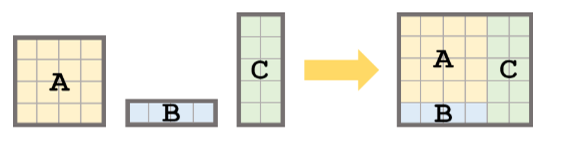

The above image illustrates graphically how this operation should take place. There is a vertical concatenation of `A` and `B`, and then a horizontal concatenation of the result with matrix `C`. Let us begin by defining the three matrices: 

syms a11 a12 a13 a14 a21 a22 a23 a24 a31 a32 a33 a34 a41 a42 a43 a44 b11 b12 b13 b14 c11 c12 c21 c22 c31 c32 c41 c42 c51 c52
A = [a11 a12 a13 a14;
     a21 a22 a23 a24;
     a31 a32 a33 a34;
     a41 a42 a43 a44];
B = [b11 b12 b13 b14];
C = [c11 c12;
     c21 c22;
     c31 c32;
     c41 c42;
     c51 c52];

As described above, concatenate matrix `A` and `B` vertically (`[A; B]`) and then horizontally concatenate that resulting matrix with matrix `C (NewMatrix = [[A; B] C]):`

NewMatrix = [[A; B] C]

$$NewMatrix = \left(\begin{array}{cccccc} a_{11} & a_{12} & a_{13} & a_{14} & c_{11} & c_{12}\\ a_{21} & a_{22} & a_{23} & a_{24} & c_{21} & c_{22}\\ a_{31} & a_{32} & a_{33} & a_{34} & c_{31} & c_{32}\\ a_{41} & a_{42} & a_{43} & a_{44} & c_{41} & c_{42}\\ b_{11} & b_{12} & b_{13} & b_{14} & c_{51} & c_{52} \end{array}\right)$$

Now you try! Create a matrix array, `A`, with element values `1`, `2`, `4`, and `5`, and a column vector array, `b`, with element values `3`, and `6`. Horizontally concatenate the vector array to the right-hand side of the matrix array. 

A =[1 2; 4 5];
b = [3; 6];
[A, b]

ans =      1     2     3
     4     5     6


### **Operate with functions on arrays**

Many built in functions of MATLAB can be applied directly to arrays, eliminating the need for iterating through each element of an array. In this subsection we will consider basic, element-wise arithmetic, and then operate on an array with three (of many) mathematical functions.

At this point in your academic year, you have likely covered some linear algebra operations, including matrix multiplication and "division" (using the transpose of a matrix). These are different operations from element-wise multiplication and division, in that they operate on the whole row or column of the array and not just a single element position at a time. See documentation on [`mtimes`](https://www.mathworks.com/help/matlab/ref/mtimes.html) and [`mrdivide`](https://www.mathworks.com/help/fixedpoint/ref/embedded.fi.mrdivide.html) for more information on these matrix operations. Let us now demonstrate some basic, element-wise arithmetic. 

To get us started, let us define 2 vector arrays `a` and `b` with `5` equally spaced element values as follows:

a = 10:10:50
b = 5:-1:1

Let us consider the element-wise multiplication and division of the vector arrays `a` and `b`, denoted respectively by the operators `.*` and `./` 

a.*b

a =     10    20    30    40    50


a./b

b =      5     4     3     2     1


Note that the vector arrays, `a` and `b`, have the same dimensions, and the output has the same dimensions as the input arrays. Consult the documentation for [`times`](https://www.mathworks.com/help/matlab/ref/times.html) and [`rdivide`](https://www.mathworks.com/help/matlab/ref/rdivide.html) for more information about their other operating properties.

Now you try! Consider the following 2 vector arrays, `quantity`, `price_per_pack`, which represent the number of pears in a fruit pack, and its corresponding selling price in ZAR per fruit pack, respectively. 

quantity = 2:2:8;

ans =     50    80    90    80    50


price_per_pack = [10 18 25.5 30];

ans =      2     5    10    20    50


Determine the selling price per unit (pear) when a fruit pack is chosen, i.e. use element-wise division of `price_per_pack` by `quantity`.

price_per_pack./quantity

There are many operators that can be applied directly to arrays, including trigonometric, logarithmic, and other mathematical functions. Let us demonstrate this by first creating an array of values in the interval $\left\lbrack 0,2\pi \right\rbrack$, and then operating on the array with the `sin`, `tan`, and `log` functions.

x = linspace(0,2*pi)
y_1 = sin(x)
y_2 = tan(x) 

ans =    5.000000000000000   4.500000000000000   4.250000000000000   3.750000000000000


y_3 = log(x)

Note that all 100 evaluated values of each function were generated with a single line of code. If you are unsure of whether a function can operate on an array, search for its definition in the documentation either by:

- Using the *Search Documentation* box on the top right-hand corner of the MATLAB user interface 

- Typing the function in a code section or the command window and press `F1` or right-click and select *Help on "Function"* 

If the function does not operate on an array, make use of the `arrayfun` function. See [arrayfun documentation](https://www.mathworks.com/help/matlab/ref/arrayfun.html) for more on this. 

Now you try! Create a row vector array, `x`, with 5 equally spaced element values between `-1` and `1`. Determine the absolute value of this array using the `abs` function. 

x = linspace(-1, 1, 5)

x =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


abs(x)

y_1 =          0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0.0951    0.0317


y_2 =          0    0.0636    0.1276    0.1927    0.2595    0.3284    0.4003    0.4760    0.5564    0.6427    0.7363    0.8391    0.9535    1.0827    1.2309    1.4043    1.6117    1.8664    2.1897    2.6175    3.2160    4.1221    5.6713    8.9666   20.9926  -63.0201  -12.5786   -6.9552   -4.7792   -3.6170   -2.8893   -2.3874   -2.0177   -1.7321   -1.5031   -1.3140   -1.1541   -1.0160   -0.8947   -0.7864   -0.6884   -0.5987   -0.5155   -0.4376   -0.3640   -0.2936   -0.2259   -0.1600   -0.0955   -0.0317


y_3 =       -Inf   -2.7572   -2.0641   -1.6586   -1.3709   -1.1478   -0.9655   -0.8113   -0.6778   -0.5600   -0.4547   -0.3593   -0.2723   -0.1923   -0.1182   -0.0492    0.0153    0.0760    0.1331    0.1872    0.2385    0.2873    0.3338    0.3783    0.4208    0.4616    0.5009    0.5386    0.5750    0.6101    0.6440    0.6767    0.7085    0.7393    0.7691    0.7981    0.8263    0.8537    0.8803    0.9063    0.9316    0.9563    0.9804    1.0040    1.0269    1.0494    1.0714    1.0929    1.1140    1.1346


x =    -1.0000   -0.5000         0    0.5000    1.0000


ans =     1.0000    0.5000         0    0.5000    1.0000


## What we've covered this week in part 1: Arrays and Matrices

This week in part 1, we learnt about: 

- What arrays and matrices are

- Creating arrays

- Indexing into arrays 

- Concatenation of arrays

- Operating with function on arrays

In the next part of this week's content, we will be learning about relational and logical operators, covering the following sub-topics: 

- Introduction to decision making with operators 

- Relational operators

- Logical operators

## Extra resources

- [Documentation: MATLAB Fundamentals](https://matlabacademy.mathworks.com/artifacts/quick-reference.html?course=mlbe&release=R2020b&language=en&) 

- [Video: How to Make a Vector in MATLAB](https://www.mathworks.com/videos/making-a-vector-the-matlab-way-97252.html?s_tid=srchtitle)

- [Video: How to Insert Data Into a Vector in MATLAB](https://www.mathworks.com/videos/inserting-data-into-a-vector-in-matlab-97214.html?s_tid=srchtitle)

- [Documentation: Removing Rows or Columns from a Matrix](https://www.mathworks.com/help/matlab/math/removing-rows-or-columns-from-a-matrix.html)

- [Video: Working with Arrays in MATLAB](https://www.mathworks.com/videos/working-with-arrays-in-matlab-69022.html?s_tid=vid_pers_recs)

- [Video: Indexing Columns and Rows](https://www.mathworks.com/videos/row-and-column-indexing-97492.html?s_tid=vid_pers_recs)

- [Documentation: Matrices and Arrays - Functions](https://www.mathworks.com/help/matlab/referencelist.html?type=function&category=matrices-and-arrays&s_tid=CRUX_topnav)

- [MATLAB Fundamentals Self-paced Course](https://matlabacademy.mathworks.com/details/matlab-fundamentals/mlbe)

- [Self-Paced Online Courses](https://matlabacademy.mathworks.com/)

## References

- [Documentation: MATLAB Fundamentals](https://matlabacademy.mathworks.com/artifacts/quick-reference.html?course=mlbe&release=R2020b&language=en&) 

- [Image Compression with Low-Rank SVD](https://www.mathworks.com/help/matlab/math/image-compression-with-low-rank-svd.html)

***Copyright 2022 The MathWorks, Inc. & Opti-Num Solutions (Pty) Ltd. ***